# Read in the tide data from NOAA

    % opts = delimitedTextImportOptions('Delimiter', ',');
    % opts.DataLines = [1, Inf]; 
    % Tides = readtable('Aug1-Nov1-Tides.csv.txt',opts);
% TidesArray=table2array(Tides);
% TideHeightDbl=cellfun(@str2double, TidesArray(:,2));  % note this gets rid of date column.  
% TideTime=datetime(TidesArray(:,1),'InputFormat','MM/dd/uuuu HH:mm');

% NOAA api tide data from Plum Island Sound
    %n = noaa("yrteIwdviqvigwZeUrwYPuWFzsmlBhei"); Web services token that
    % matlab article said was needed.  I used an url instead.
startDateTide = "20250814"; % Set the start date for tide data retrieval
% endDateTide = string(datetime("today"),'yyyyMMdd'); % Set the end date for tide data retrieval
endDateTide = "20251104";
url_plumIsland = strcat('https://api.tidesandcurrents.noaa.gov/api/prod/datagetter?product=predictions&application=NOS.COOPS.TAC.WL&begin_date=',startDateTide,'&end_date=',endDateTide,'&datum=MLLW&station=8441241&time_zone=LST&units=english&interval=&format=csv');
Tides = webread(url_plumIsland);
TidesTimetable = table2timetable(Tides);
TidesTimetable.DateTime.TimeZone = '-05:00';
    % TideHeightDbl = table2array(Tides(:,"Prediction"));
    % TideTime=table2array(Tides(:,"DateTime"));

## Get water table data

water table data from Sam.

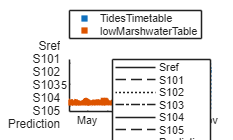

 dataDir = '..\..\';
 lowMarshwaterTable = readtimetable(fullfile(dataDir,"WaterTable\MAR-RO-Wtable-Shad-2025.csv"));
 lowMarshwaterTable.Date.TimeZone = "-05:00";
 varsWaterTable = string(lowMarshwaterTable.Properties.VariableNames);
 vars = {[varsWaterTable,"Prediction"]};
 stackedplot(TidesTimetable,lowMarshwaterTable,vars)

## Get data low marsh redox data

    %%%%%%%%%%%%%%%%%%%%%% low and high marsh redox data. lots of mismatches because of troubleshooting the voltage problems.
dataDir = '..\..\';
lowmarshtbl = importCSdata(fullfile(dataDir,'cmarsh_lowmarsh_pheno_redox.dat'));
   
oldVarnames = lowmarshtbl.Properties.VariableNames; 
lowmarshtbl.Properties.VariableNames = renameVar(oldVarnames,"low");
lowmarshtbl = removevars(lowmarshtbl,["RECORD", "PTemp_C_Avg"]); % Remove the record and p_temp columns from low marsh data
lowmarshTimetbl = table2timetable(lowmarshtbl);

Error using table2timetable (line 13)
First argument must be a table.

startDate = datetime('2025-08-16 00:00:00', TimeZone='America/New_York');
lowmarshTimetbl(lowmarshTimetbl.TIMESTAMP < startDate, :) =[];
mask = lowmarshTimetbl.L07_15cm > -300;
lowmarshTimetbl.L07_15cm(mask) = NaN;

## Get high marsh data

highmarshtblplus = importCSdata(fullfile(dataDir,'cmarshhigh_redox.dat'));  %%Note - there is an extra column here ..last one. Don't need. 
oldVarnames = highmarshtblplus.Properties.VariableNames;
highmarshtblplus.Properties.VariableNames = renameVar(oldVarnames,"high");
highmarshtbl=highmarshtblplus(:,1:33);  %This is just making life easier -- getting rid of that final column. Helps with vertcat later.
highmarshtbl15minOOPS=readtable(fullfile(dataDir,'cmarshhigh_redox.dat.backup'),opts); %There are earlier time frame data.  Time interval for some of it is 15 min instead of 5 until 8/26, and then it's 5 min again.  BUT!!! FOUND A PROBLEM> There are repeated data in there in the .backup file. lines 3183-467- are repeats. Need to remove those lines. So....
highmarshtbl15min=vertcat(highmarshtbl15minOOPS(1:3182,:),highmarshtbl15minOOPS(4671:end,:));

% lowmarsh_Array=table2array(lowmarshtbl);
% lowmarsh_ArrayDbl=cellfun(@str2double, lowmarsh_Array(:,2:33));  %This gets rid of the date column, so redox probe7  data starts at col 3 now.
% datelowmarsh=datetime(lowmarsh_Array(:,1),'InputFormat','uuuu-MM-dd HH:mm:ss');

highmarsh_Array_new=table2array(highmarshtbl);
highmarsh_Array_backup15min=table2array(highmarshtbl15min);
highmarsh_Array=vertcat(highmarsh_Array_backup15min,highmarsh_Array_new);
highmarsh_ArrayDbl=cellfun(@str2double, highmarsh_Array(:,2:33)); %Again, gets rid of date column
datehighmarsh=datetime(highmarsh_Array(:,1),'InputFormat','uuuu-MM-dd HH:mm:ss');

## Temperature correction: it's miniscule compared to the variations we see. Eh (mV) = ORP (mV) - 0.718*T + 224.41

lowmarshtemp=(lowmarsh_ArrayDbl(:,30)+lowmarsh_ArrayDbl(:,31))/2;
highmarshtemp=(highmarsh_ArrayDbl(:,30)+highmarsh_ArrayDbl(:,31))/2;

%These startDate and endDate are used in various graphs, below
startDate = datetime('2025-08-15 14:00:00');
endDate = datetime("today");
rowsToKeep = lowmarshTimetbl.TIMESTAMP >= startDate;
lowmarshTimetbl = lowmarshTimetbl(rowsToKeep,:);

## Plots

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% VARIETY OF GRAPHS OF VARYING USEFULNESS!


% timetables plots
vars = {["L07_05cm","L07_10cm","L07_15cm","L07_30cm" ],"Prediction"};
s = stackedplot(TidesTimetable,lowmarshTimetbl,vars );
s.AxesProperties(1).YLimits = [-380 -300];

%Plot low marsh redox 7 and high marsh redox 1
figure(1)
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,3:6))-(0.718*lowmarshtemp(:,1)) + 224.41),'b');
xlim([startDate endDate]);
hold on;
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,3:6))-(0.718*highmarshtemp(:,1))+224.41),'g');
xlim([startDate endDate]);
legend('Low7 5cm', 'Low7 10cm', 'Low7 15cm', 'Low7 30cm', 'High1 5cm', 'High1 10cm', 'High1 15cm', 'High1 30cm');
legend('Location','eastoutside')
hold off;
ylim([-300 300]);


figure(2) %plot low marsh redox 7,8,9 and high marsh redox 1,2
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,3:14))-(0.718*lowmarshtemp(:,1)) + 224.41),'b');
hold on;
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,3:10))-(0.718*highmarshtemp(:,1))+224.41),'g');
hold off;
ylim([-300 300]);
xlim([startDate endDate]);


figure(200) %plot low marsh redox 7,8,9 and high marsh redox 1,2
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,3:14))-(0.718*lowmarshtemp(:,1)) + 224.41));
colororder([1 0 0; 0 1 0; 0 0 1; 0 0 0]);
hold on;
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,3:10))-(0.718*highmarshtemp(:,1))+224.41));
colororder([1 0 0; 0 1 0; 0 0 1; 0 0 0]);
hold off;
ylim([-300 300]);
xlim([startDate endDate]);


figure(20) %plot ref probes relative to the one being used as reference for the profiling probes
plot(datelowmarsh(:,1),lowmarsh_ArrayDbl(:,27:29),'b');
ylim([-10 10]);
xlim([startDate endDate]);
hold on;
plot(datehighmarsh(:,1),highmarsh_ArrayDbl(:,27:29),'g');
ylim([-10 10]);
xlim([startDate endDate]);
hold off;
title('ref probe comparisons');


figure(21) %plot  ref probes relative to the one being used as reference for the profiling probes. Leave out one noisy probe lowmarsh
plot(datelowmarsh(:,1),lowmarsh_ArrayDbl(:,[27 29 32]),'b');
ylim([-10 10]);
xlim([startDate endDate]);
hold on;
plot(datehighmarsh(:,1),highmarsh_ArrayDbl(:,[27 28 29 32]),'g');
ylim([-10 10]);
xlim([startDate endDate]);
hold off;
title('ref probe comparisons');


figure(3)%show it is probe 9 that is crazy -- this is the one that bubbled when inserted
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,11:14))-(0.718*lowmarshtemp(:,1)) + 224.41),'b');
hold on;
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,3:10))-(0.718*highmarshtemp(:,1))+224.41),'g');
hold off;
ylim([-300 300]);
xlim([startDate endDate]);


figure(4)%show probes 7,8 are like MI already
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,3:10))-(0.718*lowmarshtemp(:,1)) + 224.41),'b');
hold on;
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,3:10))-(0.718*highmarshtemp(:,1))+224.41),'g');
hold off;
ylim([-300 300]);
xlim([startDate endDate]);


figure(5) %plot low marsh redox 10,11,12 and high marsh redox 3,4,5,6
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,15:26))-(0.718*lowmarshtemp(:,1)) + 224.41),'b');
hold on;
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,11:18))-(0.718*highmarshtemp(:,1))+224.41),'c');
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,19:26))-(0.718*highmarshtemp(:,1))+224.41),'g');
hold off;
ylim([-300 300]);
xlim([startDate endDate]);


figure(6) %plot low marsh redox 10,11,12 and high marsh redox 5,6  5 cm only
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,[15 19 23]))-(0.718*lowmarshtemp(:,1)) + 224.41),'b');
hold on;
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,[19 23]))-(0.718*highmarshtemp(:,1))+224.41),'g');
hold off;
ylim([-300 300]);
xlim([startDate endDate]);
title('5 cm depth only, low marsh MI probes 10,11,12; high marsh MI probes 5,6');

figure(7) %plot low marsh redox 10,11,12 and high marsh redox 5,6  10 cm only
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,[16 20 24]))-(0.718*lowmarshtemp(:,1)) + 224.41),'b');
hold on;
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,[20 24]))-(0.718*highmarshtemp(:,1))+224.41),'g');
hold off;
ylim([-300 300]);
xlim([startDate endDate]);
title('10 cm depth only, low marsh MI probes 10,11,12; high marsh MI probes 5,6');

figure(8) %plot low marsh redox 10,11,12 and high marsh redox 5,6  15 cm only
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,[17 21 25]))-(0.718*lowmarshtemp(:,1)) + 224.41),'b');
hold on;
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,[21 25]))-(0.718*highmarshtemp(:,1))+224.41),'g');
hold off;
ylim([-300 300]);
xlim([startDate endDate]);
title('15 cm depth only, low marsh MI probes 10,11,12; high marsh MI probes 5,6');

figure(9) %plot low marsh redox 10,11,12 and high marsh redox 5,6  30 cm only
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,[18 22 26]))-(0.718*lowmarshtemp(:,1)) + 224.41),'b');
hold on;
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,[21 26]))-(0.718*highmarshtemp(:,1))+224.41),'g');
hold off;
ylim([-300 300]);
xlim([startDate endDate]);
title('30 cm depth only, low marsh MI probes 10,11,12; high marsh MI probes 5,6');

figure(10) %plot low marsh redox 10,11,12 and high marsh redox 3.4  30 cm only
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,[18 22 26]))-(0.718*lowmarshtemp(:,1)) + 224.41),'b');
hold on;
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,[14 18]))-(0.718*highmarshtemp(:,1))+224.41),'g');
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,[21 26]))-(0.718*highmarshtemp(:,1))+224.41),'m');
hold off;
ylim([-300 300]);
xlim([startDate endDate]);
title('30 cm depth only, low marsh MI probes 10,11,12 blue; high marsh MI probes 3,4 green; high marsh MI 5,6 magenta');


figure(11) %plot the six redox probes from high marsh in their locations in space
t=tiledlayout(3,2,"TileSpacing","compact") 
title(t, 'High marsh redox probe layout and data - north is up')
nexttile
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,23:26))-(0.718*highmarshtemp(:,1))+224.41),'g');
title('probe6');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,19:22))-(0.718*highmarshtemp(:,1))+224.41),'g');
title('probe5');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,15:18))-(0.718*highmarshtemp(:,1))+224.41),'g');
title('probe4');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,11:14))-(0.718*highmarshtemp(:,1))+224.41),'g');
title('probe3');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,7:10))-(0.718*highmarshtemp(:,1))+224.41),'g');
title('probe2');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,3:6))-(0.718*highmarshtemp(:,1))+224.41),'g');
title('probe1');
ylim([-300 300]);
xlim([startDate endDate]);



figure(12) %plot the six redox probes from low marsh in their locations in space
t=tiledlayout(2,3,"TileSpacing","compact") 
title(t, 'Low marsh redox probe layout and data - north is up')
nexttile
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,23:26))-(0.718*lowmarshtemp(:,1))+224.41),'b');
title('probe12');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,19:22))-(0.718*lowmarshtemp(:,1))+224.41),'b');
title('probe11');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,15:18))-(0.718*lowmarshtemp(:,1))+224.41),'b');
title('probe10');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,11:14))-(0.718*lowmarshtemp(:,1))+224.41),'b');
title('probe9');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,7:10))-(0.718*lowmarshtemp(:,1))+224.41),'b');
title('probe8');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,3:6))-(0.718*lowmarshtemp(:,1))+224.41),'b');
title('probe7');
ylim([-300 300]);
xlim([startDate endDate]);

%________________________________________________________

figure(1200) %plot the six redox probes from low marsh and 5 from high marsh in their locations in space
t=tiledlayout(3,5,"TileSpacing","compact") 
title(t, 'Marsh redox probe layout and data - north is up')
nexttile
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,23:26))-(0.718*lowmarshtemp(:,1))+224.41),'b');
title('probe12');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,19:22))-(0.718*lowmarshtemp(:,1))+224.41),'b');
title('probe11');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,15:18))-(0.718*lowmarshtemp(:,1))+224.41),'b');
title('probe10');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,23:26))-(0.718*highmarshtemp(:,1))+224.41),'g');
title('probe6');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,19:22))-(0.718*highmarshtemp(:,1))+224.41),'g');
title('probe5');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile

nexttile

nexttile

nexttile
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,15:18))-(0.718*highmarshtemp(:,1))+224.41),'g');
title('probe4');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,11:14))-(0.718*highmarshtemp(:,1))+224.41),'g');
title('probe3');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,11:14))-(0.718*lowmarshtemp(:,1))+224.41),'b');
title('probe9');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,7:10))-(0.718*lowmarshtemp(:,1))+224.41),'b');
title('probe8');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datelowmarsh(:,1),((lowmarsh_ArrayDbl(:,3:6))-(0.718*lowmarshtemp(:,1))+224.41),'b');
title('probe7');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,7:10))-(0.718*highmarshtemp(:,1))+224.41),'g');
title('probe2');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,3:6))-(0.718*highmarshtemp(:,1))+224.41),'g');
title('probe1');
ylim([-300 300]);
xlim([startDate endDate]);

%_________________________________________

figure(13) %plot three redox probes from closest-to-wells transect, high marsh 
t=tiledlayout(3,1,"TileSpacing","compact") 
title(t, 'High marsh redox probe layout and data - north is up')

nexttile
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,23:26))-(0.718*highmarshtemp(:,1))+224.41));
title('probe6');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,15:18))-(0.718*highmarshtemp(:,1))+224.41));
title('probe4');
ylim([-300 300]);
xlim([startDate endDate]);

nexttile
plot(datehighmarsh(:,1),((highmarsh_ArrayDbl(:,7:10))-(0.718*highmarshtemp(:,1))+224.41));
title('probe2');
ylim([-300 300]);
xlim([startDate endDate]);



% get mean and standard deviation onto graph
% Use multidimensional arrays to get the mean and stdev of the three probes at each depth x location (low marsh) or two probes at each depth x location(high marsh), and standard deviation at each depth 


HMPrb1=((highmarsh_ArrayDbl(:,3:6))-(0.718*highmarshtemp(:,1))+224.41);
HMPrb2=((highmarsh_ArrayDbl(:,7:10))-(0.718*highmarshtemp(:,1))+224.41);
HMPrb12=cat(3,HMPrb1,HMPrb2);
HMPrb12mean=mean(HMPrb12,3);
HMPrb12stdev=std(HMPrb12,0,3);

HMPrb12mean(:,5)=mean(HMPrb12mean(:,1:4),2);
HMPrb12stdev(:,5)=std(HMPrb12mean(:,1:4),0,2);


HMPrb3=((highmarsh_ArrayDbl(:,11:14))-(0.718*highmarshtemp(:,1))+224.41);
HMPrb4=((highmarsh_ArrayDbl(:,15:18))-(0.718*highmarshtemp(:,1))+224.41);
HMPrb34=cat(3,HMPrb3,HMPrb4);
HMPrb34mean=mean(HMPrb34,3);
HMPrb34stdev=std(HMPrb34,0,3);

HMPrb34mean(:,5)=mean(HMPrb34mean(:,1:4),2);
HMPrb34stdev(:,5)=std(HMPrb34mean(:,1:4),0,2);


HMPrb5=((highmarsh_ArrayDbl(:,19:22))-(0.718*highmarshtemp(:,1))+224.41);
HMPrb6=((highmarsh_ArrayDbl(:,23:26))-(0.718*highmarshtemp(:,1))+224.41);
HMPrb56=cat(3,HMPrb5,HMPrb6);
HMPrb56mean=mean(HMPrb56,3);
HMPrb56stdev=std(HMPrb56,0,3);

HMPrb56mean(:,5)=mean(HMPrb56mean(:,1:4),2);
HMPrb56stdev(:,5)=std(HMPrb56mean(:,1:4),0,2);

HMProfileMeans(:,1)=HMPrb12mean(:,5);
HMProfileMeans(:,2)=HMPrb34mean(:,5);
HMProfileMeans(:,3)=HMPrb56mean(:,5);

HMProfileStdevs(:,1)=HMPrb12stdev(:,5);
HMProfileStdevs(:,2)=HMPrb34stdev(:,5);
HMProfileStdevs(:,3)=HMPrb56stdev(:,5);



LMPrb7=((lowmarsh_ArrayDbl(:,3:6))-(0.718*lowmarshtemp(:,1))+224.41);
     %But we have some obvious hugh peak outliers
     %HOW TO GET RID OF OUTLIERS  y_clean = filloutliers(y_raw, 'linear', 'movmedian', 11, 'SamplePoints', t);
	LMPrb7FillOutliers=filloutliers(LMPrb7,'linear','movmedian',minutes(15),'SamplePoints', datelowmarsh);
LMPrb8=((lowmarsh_ArrayDbl(:,7:10))-(0.718*lowmarshtemp(:,1))+224.41);
LMPrb9=((lowmarsh_ArrayDbl(:,11:14))-(0.718*lowmarshtemp(:,1))+224.41);
LMPrb789=cat(4,LMPrb7FillOutliers,LMPrb8, LMPrb9);
LMPrb789mean=mean(LMPrb789,4);
LMPrb789stdev=std(LMPrb789,0,4);

LMPrb789mean(:,5)=mean(LMPrb789mean(:,1:4),2);
LMPrb789stdev(:,5)=std(LMPrb789mean(:,1:4),0,2);


LMPrb10=((lowmarsh_ArrayDbl(:,15:18))-(0.718*lowmarshtemp(:,1))+224.41);
LMPrb11=((lowmarsh_ArrayDbl(:,19:22))-(0.718*lowmarshtemp(:,1))+224.41);
LMPrb12=((lowmarsh_ArrayDbl(:,23:26))-(0.718*lowmarshtemp(:,1))+224.41);
LMPrb101112=cat(4,LMPrb10,LMPrb11, LMPrb12);
LMPrb101112mean=mean(LMPrb101112,4);
LMPrb101112stdev=std(LMPrb101112,0,4);

LMPrb101112mean(:,5)=mean(LMPrb101112mean(:,1:4),2);
LMPrb101112stdev(:,5)=std(LMPrb101112mean(:,1:4),0,2);

x_datenum=datenum(datehighmarsh(:,1));
x_datenumLM=datenum(datelowmarsh(:,1));

%colors=jet(4);  jet didn't work well. So, I defined this as 
colors=([1 0 0; 0 1 0; 0 0 1; 0 0 0]);



figure(14) %%THIS WORKS!!!!
hold on;
for i=1:4
h=shadedErrorBar(x_datenum(:,1), HMPrb12mean(:,i), HMPrb12stdev(:,i), 'lineprops',{'Color', colors(i,:)} , 'patchSaturation', 0.05);
set(h.patch, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'LineStyle','none');
if isfield(h,'edge') && all(ishandle(h.edge))
    set(h.edge, 'Visible','off');
end
datetick('x', 'mmm-dd-YYYY', 'keeplimits'); 
end;
xlabel('Time');
ylabel('Eh (mV)');
ylim([-300 300])
title('Mean ± 1 Std Dev, High Marsh CB, Probes 1&2');
grid on;
legend({'5cm','10cm','15cm','30cm'});
hold off;

figure(15) %%THIS WORKS!!!!
hold on;
for i=1:4
h=shadedErrorBar(x_datenum(:,1), HMPrb34mean(:,i), HMPrb34stdev(:,i), 'lineprops',{'Color', colors(i,:)} , 'patchSaturation', 0.05);
set(h.patch, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'LineStyle','none');
if isfield(h,'edge') && all(ishandle(h.edge))
    set(h.edge, 'Visible','off');
end
datetick('x', 'mmm-dd-YYYY', 'keeplimits'); 
end;
xlabel('Time');
ylabel('Eh (mV)');
ylim([-300 300])
title('Mean ± 1 Std Dev, High Marsh 5m into MI, Probes 3&4');
grid on;
legend({'5cm','10cm','15cm','30cm'});
hold off;


figure(16) %%THIS WORKS!!!!
hold on;
for i=1:4
h=shadedErrorBar(x_datenum(:,1), HMPrb56mean(:,i), HMPrb56stdev(:,i), 'lineprops',{'Color', colors(i,:)} , 'patchSaturation', 0.05);
set(h.patch, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'LineStyle','none');
if isfield(h,'edge') && all(ishandle(h.edge))
    set(h.edge, 'Visible','off');
end
datetick('x', 'mmm-dd-YYYY', 'keeplimits'); 
end;
xlabel('Time');
ylabel('Eh (mV)');
ylim([-300 300])
title('Mean ± 1 Std Dev, High Marsh 9m into MI, Probes 5&6');
grid on;
legend({'5cm','10cm','15cm','30cm'});
hold off;


figure(160) %%THIS WORKs BUT IS NOT AT ALL HELPFUL!
hold on;
for i=1:3
h=shadedErrorBar(x_datenum(:,1), HMProfileMeans(:,i), HMProfileStdevs(:,i), 'lineprops',{'Color', colors(i,:)} , 'patchSaturation', 0.05);
set(h.patch, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'LineStyle','none');
if isfield(h,'edge') && all(ishandle(h.edge))
    set(h.edge, 'Visible','off');
end
datetick('x', 'mmm-dd-YYYY', 'keeplimits'); 
end;
xlabel('Time');
ylabel('Eh (mV)');
ylim([-300 300])
title('High marsh 9mMI 5mMI CB probes');
grid on;
legend({'CB','5','9m'});
hold off;


figure(17) %%THIS WORKS!!!!
hold on;
for i=1:4
h=shadedErrorBar(x_datenumLM(:,1), LMPrb789mean(:,i), LMPrb789stdev(:,i), 'lineprops',{'Color', colors(i,:)} , 'patchSaturation', 0.05);
set(h.patch, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'LineStyle','none');
if isfield(h,'edge') && all(ishandle(h.edge))
    set(h.edge, 'Visible','off');
end
datetick('x', 'mmm-dd-YYYY', 'keeplimits'); 
end;
xlabel('Time');
ylabel('Eh (mV)');
ylim([-300 300])
title('Mean ± 1 Std Dev, Low Marsh CB Probes7,8,9');
grid on;
legend({'5cm','10cm','15cm','30cm'});
hold off;


figure(18) %%THIS WORKS!!!!
hold on;
for i=1:4
h=shadedErrorBar(x_datenumLM(:,1), LMPrb101112mean(:,i), LMPrb101112stdev(:,i), 'lineprops',{'Color', colors(i,:)} , 'patchSaturation', 0.05);
set(h.patch, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'LineStyle','none');
if isfield(h,'edge') && all(ishandle(h.edge))
    set(h.edge, 'Visible','off');
end
datetick('x', 'mmm-dd-YYYY', 'keeplimits'); 
end;
xlabel('Time');
ylabel('Eh (mV)');
ylim([-300 300])
title('Mean ± 1 Std Dev, Low Marsh 9m into MI, Probes 10,11,12');
grid on;
legend({'5cm','10cm','15cm','30cm'});
hold off;



%%((((((((((((((((((((((((((((((((((((((((((
figure(300) %plot low and high marsh probe means and stdevs, day by day, from CB to MI. This is the graph I used in the presentation.

t=tiledlayout(3,2,"TileSpacing","compact") 
title(t, 'Marsh redox probe layout and data - north is up')

nexttile
hold on;
for i=1:4
h=shadedErrorBar(x_datenumLM(:,1), LMPrb101112mean(:,i), LMPrb101112stdev(:,i), 'lineprops',{'Color', colors(i,:)} , 'patchSaturation', 0.05);
set(h.patch, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'LineStyle','none');
if isfield(h,'edge') && all(ishandle(h.edge))
    set(h.edge, 'Visible','off');
end;
xlim([datenum('2025-08-14 14:00:00') datenum('2025-10-13 13:00:00')]);
datetick('x', 'mmm-dd-YYYY', 'keeplimits'); 
end;
xlabel('Time');
ylabel('Eh (mV)');
ylim([-300 300])
title('Low Marsh 9m into MI');
grid on;
%legend({'5cm','10cm','15cm','30cm'});
hold off;

nexttile
hold on;
for i=1:4
h=shadedErrorBar(x_datenum(:,1), HMPrb56mean(:,i), HMPrb56stdev(:,i), 'lineprops',{'Color', colors(i,:)} , 'patchSaturation', 0.05);
set(h.patch, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'LineStyle','none');
if isfield(h,'edge') && all(ishandle(h.edge))
    set(h.edge, 'Visible','off');
end;
xlim([datenum('2025-08-14 14:00:00') datenum('2025-10-13 13:00:00')]);
datetick('x', 'mmm-dd-YYYY', 'keeplimits'); 
end;
xlabel('Time');
ylabel('Eh (mV)');
ylim([-300 300])
title('High Marsh 9m into MI');
grid on;
legend({'5cm','10cm','15cm','30cm'});
legend('Location', 'eastoutside');
hold off;

nexttile

nexttile
hold on;
for i=1:4
h=shadedErrorBar(x_datenum(:,1), HMPrb34mean(:,i), HMPrb34stdev(:,i), 'lineprops',{'Color', colors(i,:)} , 'patchSaturation', 0.05);
set(h.patch, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'LineStyle','none');
if isfield(h,'edge') && all(ishandle(h.edge))
    set(h.edge, 'Visible','off');
end;
xlim([datenum('2025-08-14 14:00:00') datenum('2025-10-13 13:00:00')]);
datetick('x', 'mmm-dd-YYYY', 'keeplimits'); 
end;
xlabel('Time');
ylabel('Eh (mV)');
ylim([-300 300])
title('High Marsh 5m into MI');
grid on;
legend({'5cm','10cm','15cm','30cm'},'Location','eastoutside');
hold off;

nexttile
hold on;
for i=1:4
h=shadedErrorBar(x_datenumLM(:,1), LMPrb789mean(:,i), LMPrb789stdev(:,i), 'lineprops',{'Color', colors(i,:)} , 'patchSaturation', 0.05);
set(h.patch, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'LineStyle','none');
if isfield(h,'edge') && all(ishandle(h.edge))
    set(h.edge, 'Visible','off');
end;
xlim([datenum('2025-08-14 14:00:00') datenum('2025-10-13 13:00:00')]);
datetick('x', 'mmm-dd-YYYY', 'keeplimits'); 
end;
xlabel('Time');
ylabel('Eh (mV)');
ylim([-300 300])
title('Low Marsh CB');
grid on;
%legend({'5cm','10cm','15cm','30cm'});
hold off;

nexttile
hold on;
for i=1:4
h=shadedErrorBar(x_datenum(:,1), HMPrb12mean(:,i), HMPrb12stdev(:,i), 'lineprops',{'Color', colors(i,:)} , 'patchSaturation', 0.05);
set(h.patch, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'LineStyle','none');
if isfield(h,'edge') && all(ishandle(h.edge))
    set(h.edge, 'Visible','off');
end;
xlim([datenum('2025-08-14 14:00:00') datenum('2025-10-13 13:00:00')]);
datetick('x', 'mmm-dd-YYYY', 'keeplimits'); 
end;
xlabel('Time');
ylabel('Eh (mV)');
ylim([-300 300])
title('High Marsh CB');
grid on;
legend({'5cm','10cm','15cm','30cm'});
legend('Location', 'eastoutside');
hold off;

%%%(((((((((((((((((((((((((((((((((((((((((((((((